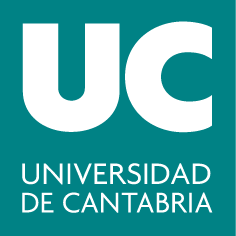

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Cálculo I**

# **5. Polinomios de Taylor**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Polinomio de Taylor

Sea $$f(x)$$ una función derivable $$n$$ veces en el punto$ $x = a$$. Se define el **polinomio de Taylor** de grado $$n$$ correspondiente a la función $$f$$ en $$x = a$$ como:

		
$$$$
		P_n(f,a) = f(a)+f'(a)(x-a) + \frac{f''(a)}{2!}(x-a)^2
	+ \frac{f'''(a)}{3!}(x-a)^3 + \ldots +\frac{f^{(n)}(a)}{n!}(x-a)^n $$$$


Si $$a = 0$$, el polinomio se llama **polinomio de Maclaurin**.

En base a esta definición, y con lo que hemos visto hasta ahora, ya podríamos calcular polinomios de Taylor.

**Ejemplo:** Calculamos el polinomio de Taylor de grado 3 de la función $$f(x)=x \,sen(x+1)$$ en el punto $$a=0$$:

clearvars
syms x real
f(x) = x*sin(x+1);          % funcion simbolica
df1(x) = diff(f, x, 1);     % primera derivada de f
df2(x) = diff(f, x, 2);     % segunda derivada de f
df3(x) = diff(f, x, 3);     % tercera derivada de f

a = 0;  % punto de aplicacion del desarrollo
pt3(x) = f(a)+df1(a)*(x-a)+df2(a)/factorial(2)*(x-a)^2 + df3(a)/factorial(3)*(x-a)^3  

Representamos la función y el polinomio de Taylor:

fplot(f, [-1 1],'k');  
hold on
fplot(pt3, [-1 1],'r--');
grid on
xlabel('x'), ylabel('y')
legend('f', 'P_3(f, 0)')
title('Funcion y polinomio de Taylor')
hold off

#### Comando `taylor`

El comando `taylor` de MATLAB permite calcular directamente el polinomio de Tayor (de cualquier grado) para una cierta función (en cualquier punto). Dicha función puede estar definida como anónima o como simbólica. El resultado que devuelve `taylor `es siempre una expresión simbólica.

Fíjate en que los argumentos de entrada `ExpansionPoint` y` Order` son opcionales. Si estos argumentos no se especifican, `taylor` calcula por defecto el polinomio de Taylor de grado 5 centrado en el punto $$x=0$$. Consulta la [documentación](https://es.mathworks.com/help/symbolic/sym.taylor.html) si quieres obtener más información.

**Ejemplo: **Utilizamos el comando `taylor` para calcular el polinomio de Taylor de grado 3 de la función $$f(x)=xsen(x+1)$$ en el punto $$x=0$$. A continuación, utiliza dicho polinomio para obtener un valor aproximado de $$0.15 \cdot sen(1.15)$$. ¿Qúe error porcentual se comete en la aproximación?

1. Definimos la función (podría ser anónima o simbólica):

syms x real  
f = @(x)  x*sin(x+1);  % funcion anonima
class(f)

2. Calculamos el polinomio de Taylor:

pt3= taylor(f, x, 0, 'Order', 3+1)  % polinomio de Taylor de orden 3 de f en el punto 0
class(pt3) 

El resultado es una variable (expresión) simbólica. Sin embargo,  si añadimos el argumento  (`pt3(x) =` ...), el resultado será una función simbólica:

pt3(x) = taylor(f, x, 0, 'Order', 3+1)  % polinomio de Taylor de orden 3 de f en el punto 0
class(pt3) 

3. Calculamos el valor exacto y valor aproximado:

ve = 0.15*sin(1.15)     % valor exacto
va = double(pt3(0.15))  % valor aproximado (necesitaremos que x=0.15)

4. Calculamos el error:

err = 100*abs((va-ve)/ve)  % error: 0.03%

#### **Comando **`taylortool`

Además del comando `taylor`, MATLAB cuenta con una herramienta gráfica para el cálculo (y visualización) de polinomios de Taylor. Para activarla, bastará con teclear` taylortool` en la ventana de comandos. Esto abrirá una ventana gráfica en la que se puede introducir por pantalla la función a aproximar, el grado que se desee para el polinomio de Taylor y el intervalo en el que se quieren representar la función y el polinomio aproximador.

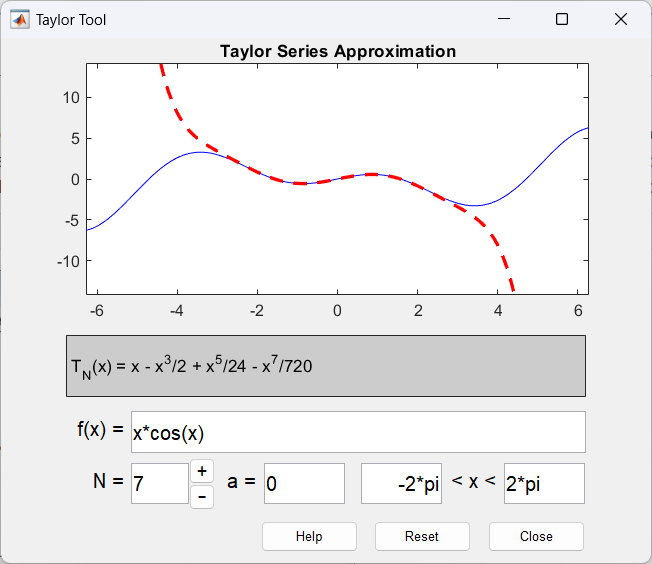

- **f(x) =**: Este campo muestra la función que se está aproximando, en este caso,$ f(x) = x \cdot \cos(x)$.

- **N**: Es el grado del polinomio de Taylor.

- **a =**: Es el punto alrededor del cual se está realizando la aproximación de Taylor. Por defecto, $a=0$, lo que significa que se está usando un polinomio de Maclaurin).

- **Rango de x**: Indica el intervalo de valores de $x$ para los que se realiza la aproximación.

**Ejercicio:** Comprueba, para la función $$f(x) = e^x \cos x$$, en un entorno del punto $$x=4$$, que a medida que el grado del polinomio de Taylor crece, éste aproxima mejor a $$f$$ y sobre un intervalo mayor. Utiliza para ello la herramienta `taylortool.`

### Bucles

#### ` for`

Llegados a este punto, conviene conocer la estructura de control más utilizada en programación, el bucle `for`, que nos permitirá automatizar la ejecución repetida de una cierta secuencia de órdenes. La estructura de un bucle en MATLAB es la siguiente:

Donde k es el contador que toma valores desde `n1` hasta` n2 (`en este caso con incremento unidad). La última iteración del bucle se produce cuando  k  llega al último valor de la secuencia a recorrer (en este caso `n2`).

**Ejemplo:** Diseñamos un bucle que muestre por pantalla el inverso de todos los número pares entre el 1 y el 20:

format rat
for k = 2:2:20   % valores a recorrer en el bucle
    disp(1/k)  % 'disp' muestra por pantalla
end

**Ejercicio:** Diseña un bucle que guarde en un vector la raíz cuadrada de los 20 primeros números naturales (excluyendo el 0):

% escribe aquí el código:




Solución:

format short
vec = zeros(1,20);  % defino vector nulo de 20 elemntos
for k = 1:20  % valores a recorrer en el bucle
    vec(k) = sqrt(k);  % voy rellenando el vector
end
vec

#### `while`

Además del bucle `for`, existe otra estructura de control muy común: el bucle `while`. A diferencia del bucle `for`, que itera un número predefinido de veces, el bucle `while` continúa ejecutando un bloque de código mientras se cumpla una condición lógica específica. Esto lo hace útil cuando no se sabe de antemano cuántas veces se necesitará repetir una operación.

- `condición`: Es una expresión lógica que se evalúa antes de cada iteración del bucle. Mientras esta condición sea verdadera (`true`), el código dentro del bucle se ejecutará repetidamente.

**Ejemplo:** Reescribimos el bucle que muestre por pantalla el inverso de todos los número pares entre el 1 y el 20:

format rat          % Cambia el formato de salida a fracción racional
k = 2;              % Inicialización de la variable k con el valor inicial 2

while k <= 20       % Bucle que se ejecuta mientras k sea menor o igual a 20
    disp(1/k)       % Muestra en pantalla el valor de 1/k 
    k = k + 2;      % Incrementa k en 2 para la siguiente iteración
end

**Ejercicio:** Diseña un bucle que guarde en un vector la raíz cuadrada de los 20 primeros números naturales (excluyendo el 0):

% escribe aquí el código:




Solución:

format short
vec = zeros(1,20);        % defino vector nulo de 20 elemntos
k = 1;
while k <=20              % valores a recorrer en el bucle
    vec(k) = sqrt(k);     % voy rellenando el vector
    k= k+1;
end
vec

**Ejercicio**: ¿Cuántos números naturales se necesitan sumar para que la suma sea mayor que 100?

% escribe aquí el código:




Solución:

S = 0; % suma
n = 0; 
while S <= 100
    n = n+1;
    S = S+n; 
end
n
% Comprobamos: 
S13 = sum(1:n-1) % debe ser <100
S14 = sum(1:n) % debe ser >100

### Ejercicios propuestos

1. Considera la función $$f(x)=x^4-5x^3+5x^2+x+2$$

- Calcula el polinomio de Taylor de grado 1 de $$f$$ en $$x=2$$. Comprueba que se trata de la recta tangente a $$f$$ en dicho punto.

- Calcula los polinomios de Taylor de grado 2,3,4,5,10. ¿Qué ocurre a partir de grado 4?

% escribe aquí el código:




Solución:

soluciones(1)

2. Considera la función $$f(x) =\ln\left(\frac{x+2}{2x-2}\right)$$

-  Dibuja en una misma gráfica $$f$ $y sus polinomios de Taylor de orden $$1$, $2$ y $3$$ en torno al punto$ $x=4$$.

- ¿Cuál es el grado del polinomio de Taylor en $$x=4$$ que habría que considerar para llegar a aproximar$ $\ln\left(\frac{6.1}{6.2}\right)$$ con un error porcentual inferior al $ $0.05\%$$?

% escribe aquí el código:






Solución:

soluciones(2)

3. Considera la función $$f(x)=\sqrt{1-\frac{x}{2}}$$

- Obtén el polinomio de Mclaurin de orden 3 para $$f(x)$$ y utilízalo para dar un valor aproximado de$ $\sqrt{0.5}$$. ¿Qué error porcentual se comete?

- Diseña un bucle que guarde en un vector el error porcentual cometido en la aproximación del apartado anterior para polinomios de Maclaurin de grado 3, 5, 8, 10, 12. Dibuja ese error en función del grado del polinomio aproximador (Utiliza el comando[ `semilogy`](https://es.mathworks.com/help/matlab/ref/semilogy.html) en lugar de `plot`). ¿Qué conclusión sacas?

- Repite el experimento propuesto en el apartado anterior pero con el objetivo de encontrar valores aproximados para $$\sqrt{0.75}$$. ¿Cómo influye el hecho de acercarse al punto en el que se hace el desarrollo ($$x=0$$ en este caso)?	

% escribe aquí el código:






Solución:

soluciones(3)

### Resumen

**Polinomio de Taylor**

- [`taylor`](https://es.mathworks.com/help/symbolic/sym.taylor.html)**:** Calcula el polinomio de Taylor de una función, permitiendo especificar el punto de expansión y el grado del polinomio. Los argumentos adicionales como el punto de expansión y el grado son opcionales; si no se especifican, se calcula un polinomio de Taylor de grado 5 centrado en 0.

- [`taylortool`](https://es.mathworks.com/help/symbolic/taylortool.html)**:** Herramienta gráfica de MATLAB que facilita el cálculo y visualización de polinomios de Taylor. Permite interactuar con la función a aproximar, elegir el grado del polinomio, el punto de expansión y el rango de valores para la variable.

**Bucles**

- [`for`](https://es.mathworks.com/help/matlab/ref/for.html)**:** Permite repetir un bloque de código un número predefinido de veces, iterando sobre un rango de valores.

- [`while`](https://es.mathworks.com/help/matlab/ref/while.html)**:** Ejecuta un bloque de código repetidamente mientras una condición lógica especificada sea verdadera, útil cuando no se conoce de antemano el número de iteraciones necesarias.

**Gráficas Logarítmicas**

- [ `semilogy`](https://es.mathworks.com/help/matlab/ref/semilogy.html)**:** Crea una gráfica donde el eje y se escala logarítmicamente, mientras que el eje x permanece en escala lineal. Es útil para visualizar datos que varían exponencialmente, permitiendo una mejor interpretación de las tendencias de crecimiento o decrecimiento.

### Soluciones 

function [] = soluciones(n)
switch n
    case 1
        % Ejercicio 1:
        fprintf("Ejercicio 1:\n");
        syms x real
        f(x) = x^4 -5*x^3 + 5*x^2 + x + 2;
        a = 2;
        %Polinomio de Taylor:

        pt1(x) = taylor(f,x,a,'Order',2);
        % Recta tangente:
        df = diff(f);

        rt(x) = df(a)*(x-a) + f(a);
        fprintf("Polinomio de Taylor: P1(x) = %s,\nRecta Tangente:          y = %s\n",char(pt1),char(rt))
        for k = [2,3,4,5,10]
            fprintf("Orden %d: ",k)
            pt(x) = taylor(f,x,a,'Order',k+1)
        end
        fprintf("A partir de grado 4, todos los polinomios de Taylor son idénticos. \nEsto se debe a que la función original es un polinomio de grado 4, \npor lo que su polinomio de Taylor de grado 4 ya es la expresión exacta. \nLos términos adicionales en polinomios de mayor grado serán cero, \nya que las derivadas de quinto orden en adelante son cero.\n")

    case 2
        % Ejercicio 2:
        fprintf("Ejercicio 2:\n");
        syms x real
        f(x) = log((x+2)/(2*x-2));
        a = 4; da = 2;
        fplot(f,[a-da,a+da],'k-','LineWidth',2)
        grid on
        hold on
        for k = 1:3
            pt(x) = taylor(f,x,a,'Order',k+1);
            leg = ['PTaylor, n = ',num2str(k)];
            fplot(pt,[a-da,a+da],'DisplayName',leg);
        end
        hold off
        legend
        x1 = 4.1;
        ve = double(f(x1));  % valor exacto
        err = 1;
        tol = 0.05;
        k = 0;
        while err > tol
            k = k+1;
            pt(x) = taylor(f,x,a,'Order',k+1);
            va = double(pt(x1));
            err=abs( (va-ve)/ve)*100;
            fprintf("Grado %d: Error = %.4f %%\n",k,err)
        end
    case 3
        % Ejercicio 3:
        fprintf("Ejercicio 3:\n");
        syms x real
        f(x) = sqrt(1-x/2);
        %1.
        maclaurin3(x) = taylor(f,x,0,'Order',4)
        x1 = solve(f-sqrt(0.5));
        va = double(maclaurin3(x1));
        ve = f(x1);
        err = abs( (va-ve)/ve)*100;
        fprintf("Valor exacto: %f, Valor aproximado: %f, Error = %.4f %%",ve, va,err)
        grados = [3,5,8,10,12];
        errores = zeros(1,length(grados));
        for k = 1:length(grados)
            order = grados(k)+1;
            pt(x) = taylor(f,x,0,'Order',order);
            va = double(pt(x1));
            errores(k)=abs( (va-ve)/ve)*100;
        end
        semilogy(grados,errores,'r-o','LineWidth',2,'DisplayName','Aproximaciones para x = 1')
        grid on
        xlabel('Grado de Polinomio de Maclaurin')
        ylabel('Error porcentual')
        %----- repetimos todo para sqrt(0.75):
        x2 = solve(f-sqrt(0.75));
        ve = f(x2);
        errores2 = zeros(1,length(grados));
        for k = 1:length(grados)
            order = grados(k)+1;
            pt(x) = taylor(f,x,0,'Order',order);
            va = double(pt(x2));
            errores2(k)=abs( (va-ve)/ve)*100;
        end
        hold on
        semilogy(grados,errores2,'b-o','LineWidth',2,'DisplayName','Aproximaciones para x = 0.5')
        hold off
        legend
end
end